k_e_init = 9.5; k_b_init = 10 - k_e_init; k_e = k_e_init; k_b = 0; % define initial rates
k = k_e + k_b; % k_tot
n_steps = 1000; N = 1; % define number of steps and serial number of branch
L_crit = 3; % minimum length needed for branching
position = 0; % where on filament branching occurs

k_bj = kbfunc(0,k_b_init,L_crit); % will keep updating as a new filament is added
prob_b = zeros(1,N); % initialize array of branching weights for each filament
direction = 0; % left/right direction at which filament grows
x = 0; % starting x-coord 
y = 0; % starting y-coord
r = 15;% radius of how far target should be
t_theta = randi([1 360],1); % random angle to pick target location
t_x = r*cosd(t_theta); % x-coord of target
t_y = r*sind(t_theta); % y-coord of target

distance = NaN; % distance from end point of filament to target
d_opt = 3; % distance required for target to be reached / radius of target

system = [1 zeros(1, n_steps - 1)];  % initialize system variable; 1 = elongate, 2 = branch
info = [0 0 1 0 0 0 0 0]; % initialize data table
% x-coord ; y-coord ; N ; N of mother branch ; length of filament; angle;
% end-x ; end-y

t_int = zeros(1,n_steps); % initialize time intervals
t_int(1) = exprnd(1/k); % randomized time interval

pick = 0; pick_e = 0; % pick_b = ? % initialize pick variable
for i = 2:n_steps
    c = rand(); % to pick elongate/branch
    t = exprnd(1/k); % time interval
    for j = 1:length(k_bj) 
        k_bj(j) = kbfunc(info(j,5), k_b_init, L_crit); % update branching rates
    end
    k_b = sum(k_bj);
    if c < k_e/(k_e+k_b) %|| sum(info(:,5) >= L_crit) < 1 % elongate (also elongating if no filament can branch yet)
        pick = 1; % system is elongating
        pick_e = fix(rand()*N) + 1; % pick which filament to elongate
        info(pick_e, 5) = info(pick_e, 5) + 1; % update data table
        end_x = info(pick_e,1) + info(pick_e,5)*cosd(info(pick_e,6));
        end_y = info(pick_e,2) + info(pick_e,5)*sind(info(pick_e,6)); % end pt coordinates of filament
        distance = sqrt((end_x - t_x)^2 + (end_y - t_y)^2); % distance from target to end pt of filament
        if distance < d_opt % filament has hit the target
            i
            break
        end
    else
        pick = 2; % system is branching
        k_bj = [k_bj 0]; % rate for new branch
        info = [info; zeros(1, width(info))]; % new row in data table
        prob_b = k_bj./sum(k_bj); % array of branching weights for each filament
        mother_b = randsample(1:N+1,1,true,prob_b); % pick where to branch
        direction = pick_dir(); % randomly picks whether to branch left or right
        N = N + 1; % new filament
        k_b = sum(k_bj);
        k_e = N*k_e_init;
        k = k_e + k_b; % update rates
        info(N,3) = N; % update serial number of new filament
        info(N,4) = mother_b; % update location of new branch
        info(N,6) = calc_angle(direction,info(mother_b, 6)); % recording angle
        position = randi(info(mother_b,5),1); % where on mother branch to create new branch
        x = info(mother_b, 1) + position*cosd(info(mother_b,6));
        y = info(mother_b, 2) + position*sind(info(mother_b,6)); % calculating coordinates of start point
        info(N,1) = x;
        info(N,2) = y; % recording coordinates of start point
    end
    system(i) = pick; % update system
    t_int(i) = t; % update time intervals
end

i =     37


% cumsum(t_int)
% system
% info % display results

x_end = info(:,1) + info(:,5).*cosd(info(:,6));
y_end = info(:,2) + info(:,5).*sind(info(:,6)); % end points of filaments
info(:,7) = x_end;
info(:,8) = y_end;
info

info =             0            0            1            0           14            0           14            0
            4            0            2            1            8           70       6.7362       7.5175
            7            0            3            1            3           70       8.0261       2.8191
       5.3681       3.7588            4            2            1            0       6.3681       3.7588
            1            0            5            1            2           70        1.684       1.8794
            9            0            6            1            0          290            9            0
            4            0            7            1            2           70        4.684       1.8794


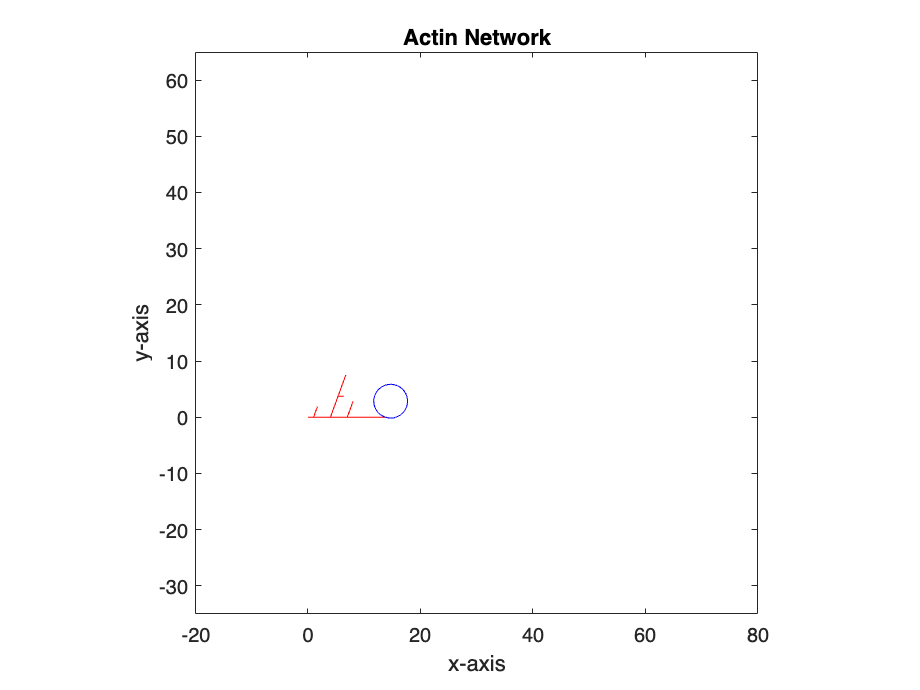


plot([info(:,1)';x_end'], [info(:,2)';y_end'],'r') % plotting actin network
title("Actin Network")
xlabel("x-axis")
ylabel("y-axis")
xlim([-20 80])
ylim([-35 65])
pbaspect([1 1 1])

hold on
theta = linspace(0,2*pi,200);
c_x = t_x + d_opt*cos(theta);
c_y = t_y + d_opt*sin(theta);
plot(c_x,c_y,'b')
hold off